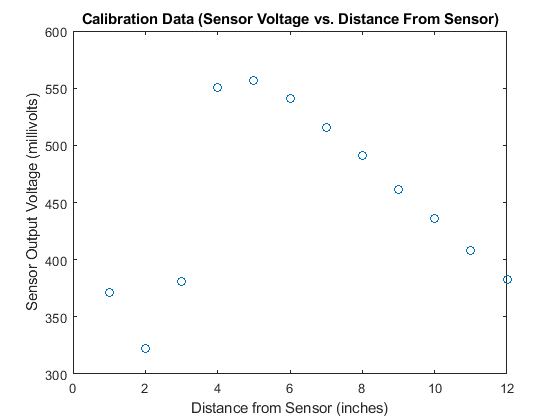

% Script to find the best-fit calibration curve given calibration data
% taken for our IR sensor from MP2.
clear
clf
syms x

% Below is hand collected calibration data, where each row represents a
% distance from 1 to 12 inches from the sensor, with 3 sensor voltages
% taken at each distance.
calibrationData = [362, 372, 380;
                   327, 319, 320;
                   390, 376, 376;
                   553, 554, 546;
                   557, 556, 557,
                   537, 540, 547;
                   517, 515, 516;
                   487, 497, 489;
                   460, 461, 463;
                   431, 442, 435;
                   407, 406, 411;
                   380, 384, 385];

% Take the average of the 3 pieces of calibration data taken at each
% distance.
averageData = mean(calibrationData, 2);

% Plot to visually identify trends in the data before using a line fitting
% tool.
plot(1:12, averageData, 'o')
title('Calibration Data (Sensor Voltage vs. Distance From Sensor)')
xlabel('Distance from Sensor (inches)')
ylabel('Sensor Output Voltage (millivolts)')

% Fit a straight line to the calibration data for distances greater than or
% equal to 5 inches from the sensor.
p = polyfit(5:12, averageData(5:12), 1);

% Fit function for distances 5 or more inches from the sensor
fitFunc = p(1) * x + p(2);

% Take the inverse of the fit function we just got, so that we can plug
% voltage into it and get distance as an output.
inverseFitFunc = finverse(fitFunc);

% compate inverse fit function to calibration data for confirmation.
hold off

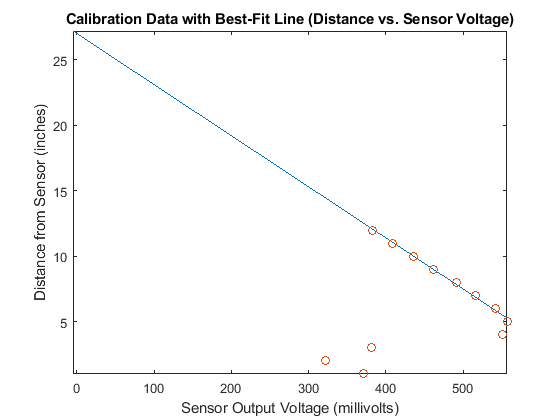

fplot(inverseFitFunc)
hold on
plot(averageData, 1:12, 'o')
title('Calibration Data with Best-Fit Line (Distance vs. Sensor Voltage)')
ylabel('Distance from Sensor (inches)')
xlabel('Sensor Output Voltage (millivolts)')

% As long as all scans are 5 or more inches away, this linear fit appears
% to be accurate.